robot = importrobot('sawyer.urdf', DataFormat='column');

bodyElbow = rigidBody('elbow');
tform = trvec2tform([0;0;0.042]');
setFixedTransform(bodyElbow.Joint,tform);
addBody(robot,bodyElbow,'right_l3');

q_with_screen = randomConfiguration(robot)

q_with_screen =     0.8708
   -5.1390
   -3.6329
   -1.7791
   -0.2748
   -2.2246
   -2.9326
    2.1393


q = q_with_screen([1 3:8]);
%q = zeros(7,1)

body_names.EE = 'right_hand';
body_names.S = 'base';
%body_names.E = 'right_l3';
body_names.E = 'elbow';
body_names.W = 'right_wrist';

tf_E = getTransform(robot, [q(1); 0; q(2:end)],body_names.E);
tf_W = getTransform(robot, [q(1); 0; q(2:end)],body_names.W);
S = [0;0;0];
E = tform2trvec(tf_E)';
W = tform2trvec(tf_W)';

tf_EE = getTransform(robot, ...
    [q(1); 0; q(2:end)],body_names.EE);
T = tform2trvec(tf_EE)'

T =    -0.4178
   -0.1959
   -0.2161


R = tform2rotm(tf_EE)

R =     0.3209    0.4969    0.8063
   -0.9437    0.0956    0.3167
    0.0803   -0.8625    0.4996



% SEW_type = "Conventional"
% psi = conv_sew(S, E, W, [0;0;1])

SEW_type = "Stereographic"

SEW_type = "Stereographic"

psi = stereo_sew(S, E, W, [0;0;-1], [1;0;0])

psi = 0.6408


GC = [-1 -1 -1];
GC([q(2) q(4) q(6)] >= 0) = 1

GC =     -1    -1    -1



q_guess = q + 0.1 * rand(size(q))

q_guess =     0.9062
   -3.5549
   -1.7355
   -0.2312
   -2.2197
   -2.9276
    2.1484


V_conv = [1;0;0];
R_stereo = [0;0;-1];
V_stereo = [1;0;0];

tic
[qq, stop_condition, err_hist] = iter_IK(R, T, psi, q_guess, kin, SEW_type, V_conv, R_stereo, V_stereo);

Unrecognized function or variable 'kin'.

toc
disp(stop_condition)

plot(vecnorm(err_hist))
err_hist = err_hist(:, ~isnan(sum(err_hist)));
err_hist(:,end)

% Test fwd_kin_diff_with_SEW

ex=[1;0;0];ey=[0;1;0];ez=[0;0;1];
zz=[0;0;0];

a1=.081;d2=.1925;d3=.4;d4=.1685;d5=.4;d6=.1363;d7=.1345;
kin.P=[0.317*ez a1*ex+d2*ey zz d3*ex-d4*ey zz d5*ex+d6*ey zz d7*ex];

kin.RT = eul2rotm(deg2rad([-90 -10 -90]));

kin.H=[ez ey ex ey ex ey ex];

kin.joint_type=[0 0 0 0 0 0 0];

[fk.R_T, fk.p_T, fk.p_E, fk.p_W, fk.J_T, fk.J_E, fk.J_W] = fwd_kin_diff_with_SEW(kin, q);

J = geometricJacobian(robot, [q(1); 0; q(2:end)],'right_hand');
J = J(:,[1,3:8]);

J_E_full = geometricJacobian(robot, z_8,'elbow');
J_W_full = geometricJacobian(robot, z_8,'right_wrist');


tic
for i = 1:50
    [fk.R_T, fk.p_T, fk.p_E, fk.p_W, fk.J_T, fk.J_E, fk.J_W] = fwd_kin_diff_with_SEW(kin, q);
end
toc

Elapsed time is 0.045853 seconds.


% Find distances in MATLAB model of sawyer
z_8 =zeros(8,1);
T_0 = getTransform(robot, z_8,'right_l0')

T_0 =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.0800
         0         0         0    1.0000


T_1 = getTransform(robot, z_8,'right_l1')

T_1 =     0.0000   -1.0000    0.0000    0.0810
         0    0.0000    1.0000    0.0500
   -1.0000   -0.0000    0.0000    0.3170
         0         0         0    1.0000


T_2 = getTransform(robot, z_8,'right_l2')

T_2 =     0.0000         0    1.0000    0.2210
         0    1.0000         0    0.1925
   -1.0000         0    0.0000    0.3170
         0         0         0    1.0000


T_3 = getTransform(robot, z_8,'right_l3')

T_3 =     0.0000   -1.0000    0.0000    0.4810
         0    0.0000    1.0000    0.1505
   -1.0000   -0.0000    0.0000    0.3170
         0         0         0    1.0000


T_4 = getTransform(robot, z_8,'right_l4')

T_4 =     0.0000         0    1.0000    0.6060
         0    1.0000         0    0.0240
   -1.0000         0    0.0000    0.3170
         0         0         0    1.0000


T_5 = getTransform(robot, z_8,'right_l5')

T_5 =     0.0000   -1.0000    0.0000    0.8810
         0    0.0000    1.0000    0.0550
   -1.0000   -0.0000    0.0000    0.3170
         0         0         0    1.0000


T_6 = getTransform(robot, z_8,'right_l6')

T_6 =     0.0000    0.0000    1.0000    0.9910
    0.1736   -0.9848   -0.0000    0.1603
    0.9848    0.1736   -0.0000    0.3170
         0         0         0    1.0000


T_EE = getTransform(robot, z_8,'right_hand')

T_EE =     0.0000   -0.0000    1.0000    1.0155
   -0.9848   -0.1736   -0.0000    0.1603
    0.1736   -0.9848   -0.0000    0.3170
         0         0         0    1.0000


q_test = deg2rad([0;0;0;0;0;0;0])

q_test =      0
     0
     0
     0
     0
     0
     0


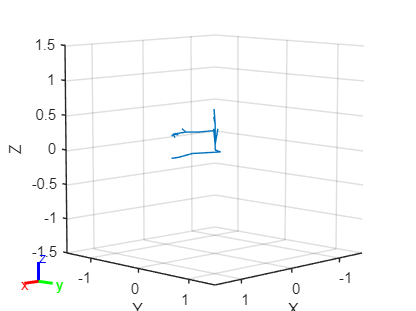

poe_robot = kin2robot(kin);
show(poe_robot, q_test);
hold on
show(robot, [q_test(1);0;q_test(2:end)], 'Visuals','off');
hold off

% Timing tests
tic
for i = 1:50
    err_vec = err_func(obj, q, R, T, SEW_type, psi);
end
toc

Elapsed time is 0.193726 seconds.


tic
for i = 1:50
    J = J_func(q);
end
toc

Elapsed time is 0.298586 seconds.


tic
for i = 1:50
    J = geometricJacobian(obj.robot, [q(1); 0; q(2:end)],'right_hand');
end
toc

Elapsed time is 0.105238 seconds.


function err_vec = err_func(obj, q, R, T, SEW_type, psi)
    tform = getTransform(obj.robot, ...
    [q(1); 0; q(2:end)],'right_hand');
    
    R_q = tform2rotm(tform);
    R_err = R_q * R';
    axang = rotm2axang(R_err);
    err_angle = axang(4) * axang(1:3);

    err_xyz = tform2trvec(tform)' - T;
    
    [S, E, W] = get_SEW_pos_by_q(obj, q);
    if SEW_type == "Conventional"
        psi_q = conv_sew(S, E, W, obj.V_conv);
    else
        psi_q = stereo_sew(S, E, W, obj.R_stereo, obj.V_stereo);
    end

    err_psi = psi_q - psi;

    err_vec = [err_angle'; err_xyz ; err_psi];
end

function [S, E, W] = get_SEW_pos_by_q(obj, q)
    tf_E = getTransform(obj.robot, [q(1); 0; q(2:end)],'right_l3');
    tf_W = getTransform(obj.robot, [q(1); 0; q(2:end)],'right_wrist');
    S = [0;0;0];
    E = tform2trvec(tf_E)';
    W = tform2trvec(tf_W)';
end

function J_A = augmented_jacobian_by_q(obj, SEW_type, q)
    J = geometricJacobian(obj.robot, [q(1); 0; q(2:end)],'right_hand');
    J = J(:,[1,3:8]);
    
    J_E_full = geometricJacobian(obj.robot, [q(1); 0; q(2:end)],'right_l3');
    J_E_full = J_E_full(:,[1,3:8]);
    J_E_pos = J_E_full(4:6, :);
    
    J_W_full = geometricJacobian(obj.robot, [q(1); 0; q(2:end)],'right_wrist');
    J_W_full = J_W_full(:,[1,3:8]);
    J_W_pos = J_W_full(4:6, :);

    [S, E, W] = get_SEW_pos_by_q(obj, q);

    if SEW_type == "Conventional"
        [J_psi_e, J_psi_w] = conv_sew_jacobian(S, E, W, obj.V_conv);
    else
        [J_psi_e, J_psi_w] = stereo_sew_jacobian(S, E, W, obj.R_stereo, obj.V_stereo);
    end

    J_psi = J_psi_e * J_E_pos + J_psi_w * J_W_pos;
    J_A = [J; J_psi];      
end